% What does it show
% TO CHANGE
% This example shows how to detect a cell using edge 
% detection and basic morphology. An object can be 
% easily detected in an image if the object has 
% sufficient contrast from the background.

% System Config
format shortG;
format compact;
% set(0,'DefaultFigureWindowStyle','docked')

filename = "FLIR0206v2.mp4";
main_operator = "to crop";
% main(filename, main_operator)

% Step 0: Get data
vidObj = VideoReader(filename);

numFrames = vidObj.NumFrames;

Height = vidObj.Height;
Width = vidObj.Width;

% empty_struct = container(Height, Width);
% populated_struct = populateStruct(vid, empty_struct);

% % Create an emptry strucure that will hause the video frame data
% function structure = container(Height, Width)
% structure = struct('colordata',zeros(Height,Width,3,'uint8'),...
%     'colormap',[]);
% end
% 
% % Populate the empty strucure from container function with frame 
% % data from the video
% function empty_struct = populateStruct(video, empty_struct)
% while hasFrame(video)
%     nthframe = ceil(video.CurrentTime*video.FrameRate);
%     empty_struct(nthframe).colordata = readFrame(video);
%     % save the frame as a .jpg image
%     % imwrite(empty_struct(nthframe).colordata, strcat(...
%     %     './frames/frame', num2str(nthframe), '.jpg'));
% end
% end

sampleFrame = read(vidObj, 1);
% imshow(sampleFrame)

% Noise regions
% Noise boxes that are to be ignored during the image processing 
distoredRegions = getBoxes(vidObj);
% imshow(distoredRegions)
% title('Initially identified boxes')
vidObj.CurrentTime = 0;
secondDistoredRegions = edge(rgb2gray(sampleFrame), 'sobel', 0.25);
% Add a strel (possible a disc) to fill the gaps
distoredRegions(secondDistoredRegions==1) = 0;
% imshow(distoredRegions)
% title('Final Noise Regions')

## TO SORT POINTER, FILL

% Creates an image containing the position and the values of noise 
% created by the camera pointer
pointerOutliner = ones(Height, Width);
pointerOutliner(Height/2-15:Height/2+15, Width/2-15:Width/2+15) = ...
    distoredRegions(Height/2-15:Height/2+15, Width/2-15:Width/2+15);
% imshow(pointerOutliner)

## TO CHANGE COLOR BOX

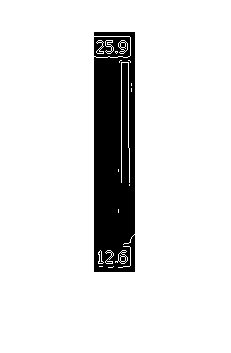


figure; imshow(rgb2ind(frame, 64))
figure; imshow(rgb2ind(frame, 128))
figure; imshow(rgb2ind(frame, 256))
figure; imshow(rgb2ind(frame, 512))
figure; imshow(rgb2ind(frame, 1024))
figure; imshow(rgb2ind(frame, 2048))

BW = edge(rgb2gray(sampleFrame), 'sobel');
colorScaleRegion = BW(:, end-40:end);
% imshow(colorScaleRegion)


% Cropped values for colorbar 
colorBar = [25, 200, 303, 303+15];
imageCrop = [140, 240, 100, 200];



% Storage variables
storedData(numFrames) = struct(...
    'colordata', zeros((imageCrop(2) - imageCrop(1)), (imageCrop(4) - imageCrop(3)), 3), ...
    'colormap', zeros((colorBar(2) - colorBar(1)), (colorBar(4) - colorBar(3)), 3), ...
    'MaxTemp', zeros(numFrames), ...
    'MinTemp', zeros(numFrames) ...
    );

% Number of segmentations
nRegions = 20;

% second storage variable
data=zeros(numFrames,nRegions,3);



% read the next frame
% RGBframe = readFrame(vidObj);
RGBframe = sampleFrame;
% find which frame has been read
nthframe = ceil(vidObj.CurrentTime*vidObj.FrameRate);


## To get binary green channel image

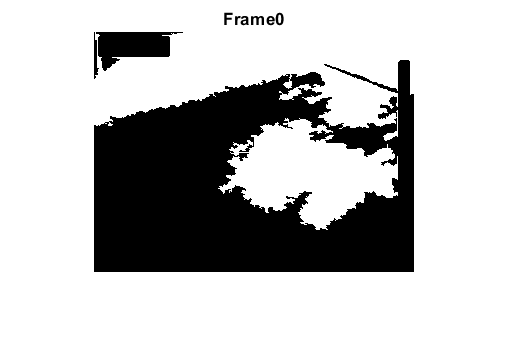


% Create a binary image
binaryImage = greenChannel > 13;
% Fill holes
binaryImage = imfill(binaryImage, 'holes');
% Get rid of small particles less than 10000 pixels in area.
binaryImage = bwareaopen(binaryImage, 10000);

figure; imshow(binaryImage)
title(strcat('Frame ', num2str(nthframe)))    


% Undestorted image
CroppedRGBFrame = RGBframe(imageCrop(1):imageCrop(2), imageCrop(3):imageCrop(4), :);

Unrecognized function or variable 'RGBframe'.

% Colorbar
CroppedRGBColorBar = RGBframe(colorBar(1):colorBar(2), colorBar(3):colorBar(4), :);


% Cropping the section where high temp reading is
highTempCrop = colorScaleRegion;
% Cropping the section where low temp reading is
lowTempCrop = colorScaleRegion;
% OCR (optical character recognition) on the image
% Find the value for the high temp based on the image
highTemp = GetTempNumber(highTempCrop);
% Find the value for the low temp based on the image
lowTemp = GetTempNumber(lowTempCrop);

% checks if the OCR method has worked succefully and has returned wrong
% values
if highTemp < lowTemp
    error('there is a issue in the ocr method')
end


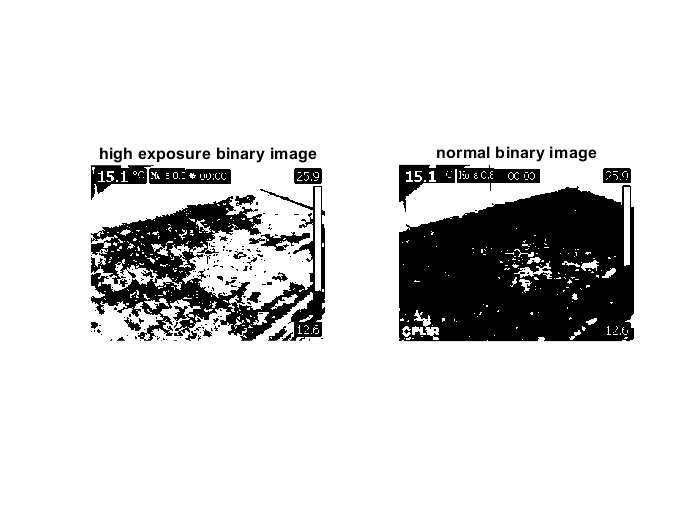


% Generates an image that contains the temperature values of each pixel
% based on the colorbar
tempImage = convertToThermalImage(CroppedRGBFrame, CroppedRGBColorBar, highTemp, lowTemp);

threshold = highTemp; ...(lowTemp+highTemp)/1.5;
pos = find(tempImage>threshold-0.5 & tempImage<threshold+0.5);
row = rem(pos(1), size(RGBframe, 1));
col = ceil(pos(1)/size(RGBframe, 2));
highLevelExposure = imbinarize(rgb2gray(RGBframe), ...
    double(rgb2gray(RGBframe(row, col, :)))/255);
originalBinary = imbinarize(rgb2gray(RGBframe));

figure; 
subplot(1,2,1); imshow(highLevelExposure); title('high exposure binary image')
subplot(1,2,2); imshow(originalBinary); title('normal binary image')

%     reducedFrameAnalysis(frameName, 'sobel')
    reducedFrameAnalysisv2(RGBframe, 'sobel')

GrayImage = rgb2gray(ImageRaw);
[~,threshold] = edge(GrayImage,method);

fudgeFactor = 0.5;
BWs = edge(GrayImage,method,threshold * fudgeFactor);
figure; imshow(BWs); title('Edge only')
se90 = strel('line',3,90);
se0 = strel('line',3,0);
BWsdil = imdilate(BWs,[se90 se0]);

BWdfill = imfill(BWsdil,'holes');

seD = strel('diamond',1);
BWfinal = imerode(BWdfill,seD);
BWfinal = imerode(BWfinal,seD);

figure;
subplot(1, 2, 2);
% figure; imshow(labeloverlay(GrayImage,BWsdil))
imshow(labeloverlay(GrayImage,BWdfill)); title('overlayed edge detection')
% figure; imshow(labeloverlay(GrayImage,BWfinal))


% BWoutline1 = bwperim(BWsdil);
% Segout1 = GrayImage; 
% Segout1(BWoutline1) = 255; 
% figure; imshow(Segout1)
% 
BWoutline2 = bwperim(BWdfill);
Segout2 = GrayImage; 
Segout2(BWoutline2) = 255; 
subplot(1, 2, 1);
imshow(Segout2); title('darkened gray image')



    
    %% To test
    
%     % %% apply edge to lab image
%     imshow(rgb2lab(RGBframe))
%     % try bounding box
%     imshow(rgb2hsv(RGBframe))
%     imshow(rgb2ycbcr(RGBframe))
%     
%     
%     rgb2lab(RGBframe)
%     roipoly
%     
%     sample_region = [50 100 50 100]; % region of interest
%     x = RGBframe;
%     cform = makecform('srgb2lab');
%     lab_x = applycform(x, cform);
%     
%     a = lab_x(:, :, 2);
%     b = lab_x(:, :, 3);
%     color_markers = repmat(0, [6, 2]); % 6 - number of regions
%     for cc = 1:6
%         color_markers(cc, 1) = mean2(a(sample_region(:,:,cc)));
%         color_markers(cc, 2) = mean2(b(sample_region(:,:,cc)));
%     end
% %%    SEGMENT IMAGE






% %% Labelling of binary image
% % Label each blob with 8-connectivity, so we can make measurements of it
% [labeledImage, numberOfBlobs] = bwlabel(binaryImage, 8);
% % Apply a variety of pseudo-colors to the regions.
% coloredLabelsImage = label2rgb (labeledImage, 'hsv', 'k', 'shuffle'); 
% % Display the pseudo-colored image.
% subplot(3, 3, 3);
% imshow(coloredLabelsImage);
% title('Labeled Image', 'FontSize', fontSize);
% % Get all the blob properties.
% blobMeasurements = regionprops(labeledImage, 'all')
% numberOfBlobs = size(blobMeasurements, 1)

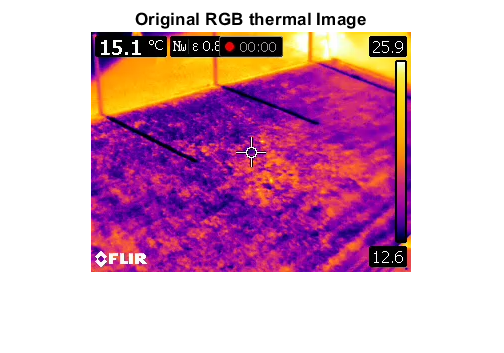

% Step 1: Read Image
% Read in the cell.tif image, which is an image of a 
% prostate cancer cell. Two cells are present in this 
% image, but only one cell can be seen in its entirety. 
% The goal is to detect, or segment, the cell that 
% is completely visible.
imshow(sampleFrame)
title('Original RGB thermal Image');

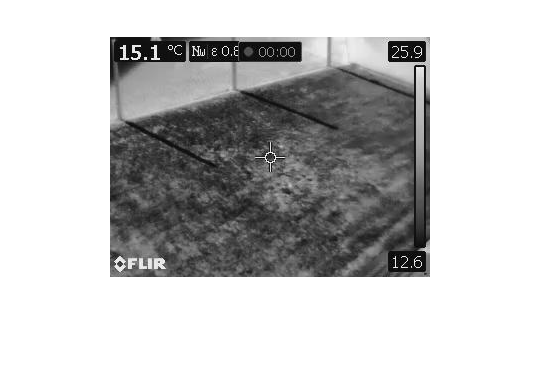

I = rgb2gray(frame);
imshow(I)

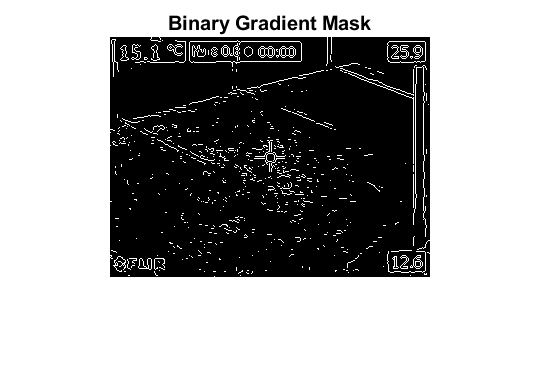

% Step 2: Detect Entire Cell
% The object to be segmented differs greatly in contrast from the background image. Changes in contrast can be detected by operators that calculate the gradient of an image. To create a binary mask containing the segmented cell, calculate the gradient image and apply a threshold.
% Use edge and the Sobel operator to calculate the threshold value. Tune the threshold value and use edge again to obtain a binary mask that contains the segmented cell.
[~,threshold] = edge(I,'sobel');
fudgeFactor = 0.5;
BWs = edge(I,'sobel',threshold * fudgeFactor);
% Display the resulting binary gradient mask.
imshow(BWs)
title('Binary Gradient Mask')

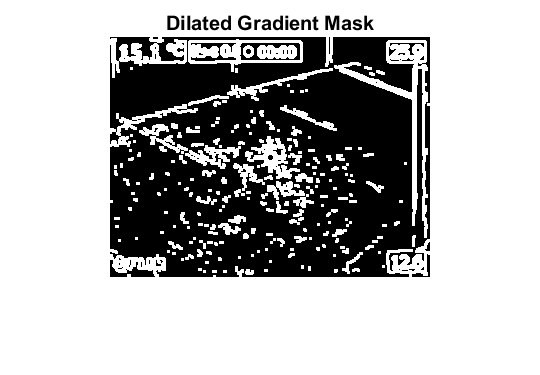


% Step 3: Dilate the Image
% The binary gradient mask shows lines of high contrast in the image. These lines do not quite delineate the outline of the object of interest. Compared to the original image, there are gaps in the lines surrounding the object in the gradient mask. These linear gaps will disappear if the Sobel image is dilated using linear structuring elements. Create two perpindicular linear structuring elements by using strel function.
se90 = strel('line',3,90);
se0 = strel('line',3,0);

% Dilate the binary gradient mask using the vertical structuring element followed by the horizontal structuring element. The imdilate function dilates the image.
BWsdil = imdilate(BWs,[se90 se0]);
imshow(BWsdil)
title('Dilated Gradient Mask')

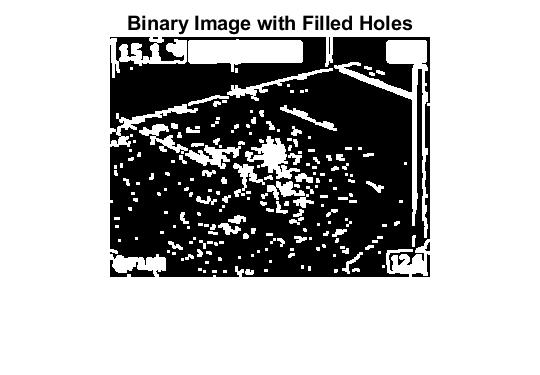


% Step 4: Fill Interior Gaps
% The dilated gradient mask shows the outline of the cell quite nicely, but there are still holes in the interior of the cell. To fill these holes, use the imfill function.
BWdfill = imfill(BWsdil,'holes');
imshow(BWdfill)
title('Binary Image with Filled Holes')

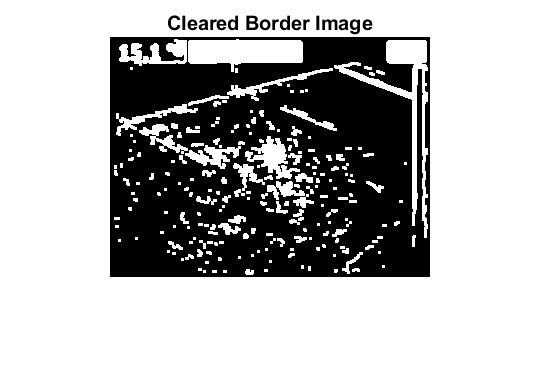


% Step 5: Remove Connected Objects on Border
% The cell of interest has been successfully segmented, but it is not the only object that has been found. Any objects that are connected to the border of the image can be removed using the imclearborder function. To remove diagonal connections, set the connectivity in the imclearborder function to 4.
BWnobord = imclearborder(BWdfill,4);
imshow(BWnobord)
title('Cleared Border Image')

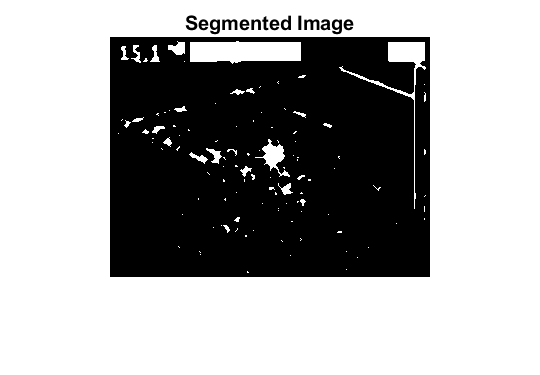


% Step 6: Smooth the Object
% Finally, in order to make the segmented object look natural, smooth the object by eroding the image twice with a diamond structuring element. Create the diamond structuring element using the strel function.
seD = strel('diamond',1);
BWfinal = imerode(BWnobord,seD);
BWfinal = imerode(BWfinal,seD);
imshow(BWfinal)
title('Segmented Image');

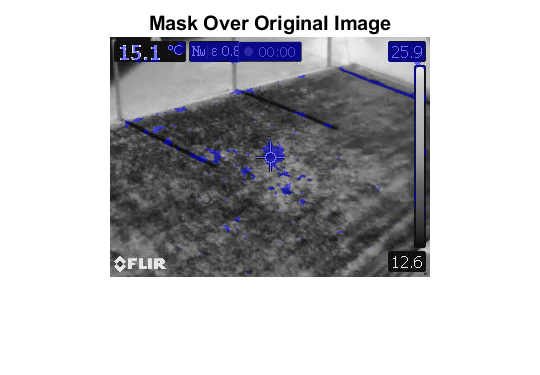


% Step 7: Visualize the Segmentation
% You can use the labeloverlay function to display the mask over the original image.
imshow(labeloverlay(I,BWfinal))
title('Mask Over Original Image')

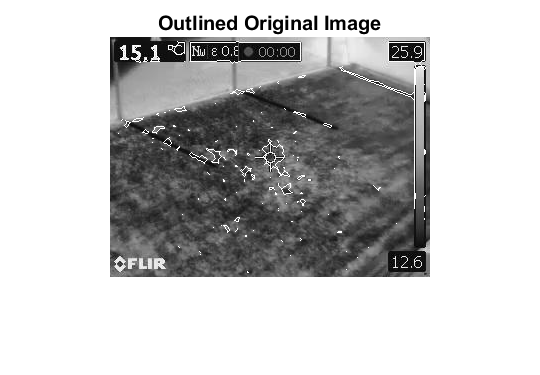

% An alternate method to display the segmented object is to draw an outline around the segmented cell. Draw an outline by using the bwperim function.
BWoutline = bwperim(BWfinal);
Segout = I; 
Segout(BWoutline) = 255; 
imshow(Segout)
title('Outlined Original Image')

% Copyright 2004-2013 The MathWorks, Inc.

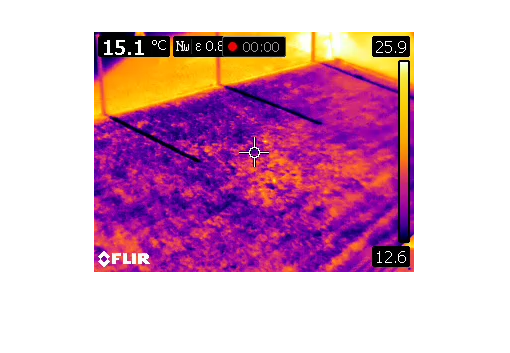

figure; imshow(sampleFrame)

% figure; imshow(I)
figure; imshow(BWs)

Unrecognized function or variable 'BWs'.

figure; imshow(BWsdil)
figure; imshow(BWdfill)
figure; imshow(BWnobord)
figure; imshow(BWfinal)
figure; imshow(labeloverlay(I,BWfinal))
figure; imshow(Segout)

%% TO CHECK

function [data, Lout] = VideoAnalyser(numFrames, s, nreg)
data=zeros(numFrames,nreg,3);

take_ref = 1:100:numFrames;

for nframe = 1:numFrames
    if find(take_ref==nframe)
       Aref=s(nframe).colordata;
       Alab_ref=rgb2lab(Aref);
    end
    
    A=s(nframe).colordata;
    Alab = rgb2lab(A);
    [L,N] = superpixels(Alab_ref,nreg,'isInputLab',true);
    BW = boundarymask(L);
    %f1=figure();
    imshow(imoverlay(A,BW,'cyan'))
    pixelIdxList = label2idx(L);
    meanColor = zeros(N,3);
    [m,n] = size(L);
    for  i = 1:N
        meanColor(i,1) = median(Alab(pixelIdxList{i}));
        meanColor(i,2) = median(Alab(pixelIdxList{i}+m*n));
        meanColor(i,3) = median(Alab(pixelIdxList{i}+2*m*n));
        data(nframe, i,1) = meanColor(i,1); 
        data(nframe, i,2) = meanColor(i,2) ;
        data(nframe, i,3) = meanColor(i,3); 
    end
    numColors = nreg;
%     idx = kmeans(meanColor,numColors,'replicates',2);
    [idx,cmap] = kmeans(meanColor,numColors,'replicates',2);
    cmap = lab2rgb(cmap);
    Lout = zeros(size(A,1),size(A,2));
    for j = 1:N
        Lout(pixelIdxList{j}) = idx(j);
    end
%     f2=figure();
% 
%     imshow(label2rgb(Lout))
%     f3=figure();
% 
%     imshow(Lout,cmap)
end
end

function DataPlotter(numFrames, nreg, data)
figure;
grid on
hold on
% c = linspace(0,1,nreg);
rgb=jet(nreg);
% tic,
for N = 1:nreg
%     c(N)
%     rgb(N,:)
    scatter(linspace(0,1,numFrames), data(:,N,1),25,rgb(N,:));
end
% toc,
end